clc;
h5path = 'C:\Users\RBO\Documents\data\high_res\extracted_5px_5px_17px_0px';
mcpath = 'C:\Users\RBO\Documents\data\high_res\corrected_5px_5px_17px_0px';

## Optional: Rename planes

clc;
order = fliplr([1 5:10 2 11:17 3 18:23 4 24:30]);
% rename_planes(mcpath, order);

plane = 26;
v2_path = 'C:/Users/RBO/Documents/data/high_res/extracted_5px_5px_17px_0px';
v2 = sprintf('%s/motion_corrected_reordered_plane_%d.h5', v2_path, plane);
gt = sprintf('C:/Users/RBO/Documents/data/ground_truth/high_res/Fig4a-c_dataset_plane_%d.mat', plane);
Ym_v2 = mean(read_plane(v2_path, '/Y', 1, 1:1730),3);
Ym_gt = matfile(gt).Ym;

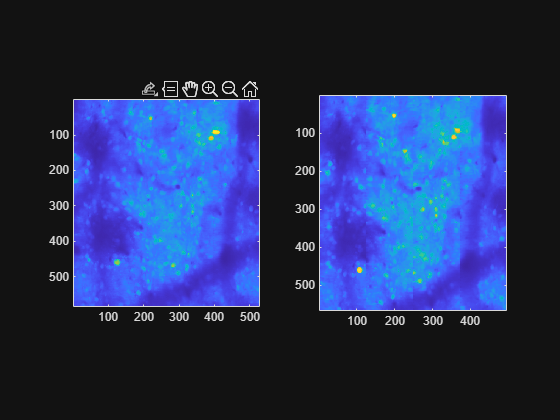

figure; subplot(1,2,1); imagesc(matfile(gt).Ym); axis image; subplot(1,2,2); imagesc(Ym_v2); axis image;

## Bi-hemisphere Plane 30 (reordered from plane 1) motion correction validation

% ground truth
data = matfile("C:\Users\RBO\Documents\data\ground_truth\bi_hemisphere\MH184_both_6mm_FOV_150_600um_depth_410mW_9min_no_stimuli_00001_plane_30.mat");
[yind, xind] = get_central_indices(data.Y(:,:,4), 200);
planeToMovie(data.Y(yind, xind, :), "C:\Users\RBO\Documents\data\bi_hemisphere\gt_plane30", 9.6);

data_name = fullfile("C:\Users\RBO\Documents\data\bi_hemisphere\corrected\motion_corrected_plane_1.h5");
h5info(data_name, '/').Datasets
data_new = h5read(data_name, '/mov');

[yind, xind] = get_central_indices(data_new(:,:,4), 200);
planeToMovie(data_new(yind, xind, :), "C:\Users\RBO\Documents\data\bi_hemisphere\new_plane", 9.6);

segment_path = fullfile('C:\Users\RBO\Documents\data\bi_hemisphere\results\');
ym_path = fullfile('C:\Users\RBO\Documents\data\bi_hemisphere\corrected\');

ym_files = dir([ym_path '*_plane_*.h5*']);
segment_files = dir([segment_path '*_plane_*.h5*']);

for i=1:length(ym_files)
    fname = fullfile(ym_files(i).folder, ym_files(i).name);
    sname = fullfile(segment_files(i).folder, segment_files(i).name);
    Ym = mean(h5read(fname, '/mov'),3);
    h5create(sname, '/Ym', size(Ym));
    h5write(sname, '/Ym', Ym);
end
% save_path = fullfile(segment_path, "axial_offset");
